# Real Mass Matrix

Yo calulculate the real mass matrix  frist we devivided the Sparus into 8 different elements. For each element we will calculate a  real mass matrix, translate it into the center of mass of the SPARUS, and finally we will add ll the element matrices into a Total Mass matrix 

The elements are the following: 

- Cilinder 

- Top sphere

- Bottom sphere

- Antena

- Thruster 1

- Thruster 2 

- Sensor 1 

- Sensor 2

## Volumes

v_cylinder = 0.0519;
v_topsphere = 0.0078;
v_bottomsphere = 0.0028;
v_antena = 0.00059;
v_thruster1 =  0.0003965;
v_thurster2 = 0.0003965;
v_sesnor1 =  0.000098;
v_sensor2 = 0.000059;

Each volume was calulated using regular volumetric formulas, excpet for bottom sphere which was calulated by measurmente 5 diferent points and aporximating a function that has a similar shape than the sphere. then integrating.

 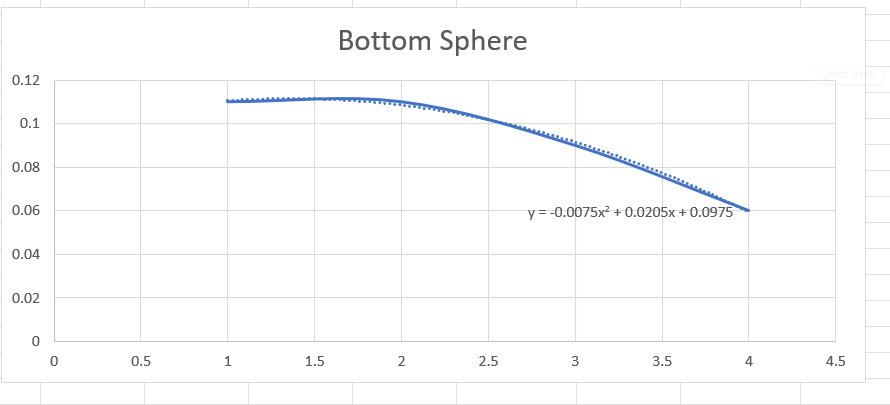

- From this experiment, comparing wiht values form collegues,  we can can determine that  even though this method is more accurate the diference between integratign the curve and usign a simple shape like a sphere  is negligable (10e-3) so for future Drag and Added mass matrix  common geometry will be used for the sake of simpler calculations. 

We made the asumption that every part of the SPARUS has the same density. 

total_volume = v_cylinder+v_sensor2+v_sesnor1+v_thurster2+v_thruster1+v_bottomsphere+v_topsphere+v_antena

total_volume = 0.0640

From the total volume and the weight we can calulate the denisty to finally compute the mass of each element 

## Masses

m_SPARUS = 52;
density_SPARUS = m_SPARUS/total_volume 

density_SPARUS = 811.9925


m_cylinder = v_cylinder*density_SPARUS

m_cylinder = 42.1424

m_topsphere = v_topsphere*density_SPARUS

m_topsphere = 6.3335

m_bottomsphere = v_bottomsphere*density_SPARUS

m_bottomsphere = 2.2736

m_antena = v_antena*density_SPARUS

m_antena = 0.4791

m_thruster1 =  v_thruster1*density_SPARUS

m_thruster1 = 0.3220

m_thurster2 = v_thurster2*density_SPARUS

m_thurster2 = 0.3220

m_sensor1 =  v_sesnor1*density_SPARUS

m_sensor1 = 0.0796

m_sensor2 = v_sensor2*density_SPARUS

m_sensor2 = 0.0479


total_mass =m_cylinder+m_sensor2+m_sensor1+m_thurster2+m_thruster1+m_bottomsphere+m_topsphere+m_antena

total_mass = 52.0000

The following  table shows the contribution of  every element  to the total wieght, which can give us an insight of how the system will behave according to each compotent 

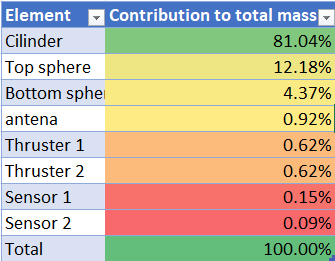

## Calculating Inertias

### Cylinder and Thrusters


$$\textrm{Ix}=\frac{1}{2}{\textrm{mr}}^2$$



$$\textrm{Iy}=\textrm{Iz}=\frac{1}{4}{\textrm{mr}}^2 +\frac{1}{12}{\textrm{mh}}^2$$


####         Cylinder

r = 0.115;
h = 1.25;

Ix =  1/2*m_cylinder*r^2;
Iy = 1/4*m_cylinder*r^2 + 1/12*m_cylinder*h^2;
Iz = Iy;



Building the matrix:  

mat_cyl = RealMassMatrixbuilder(m_cylinder, Ix, Iy, Iz)

mat_cyl =    42.1424         0         0         0         0         0
         0   42.1424         0         0         0         0
         0         0   42.1424         0         0         0
         0         0         0    0.2787         0         0
         0         0         0         0    5.6266         0
         0         0         0         0         0    5.6266


Tranlsating the matrix from element  body center to   SPARUS Grav 

trans_cyl = Translation(0.12, 0, 0, mat_cyl)

trans_cyl =    42.1424         0         0         0         0         0
         0   42.1424         0         0         0    5.0571
         0         0   42.1424         0   -5.0571         0
         0         0         0    0.2787         0         0
         0         0   -5.0571         0    6.2335         0
         0    5.0571         0         0         0    6.2335


####         Thruster 1

r = 0.035;
h = 0.25;

Ix =  1/2*m_thruster1*r^2;
Iy = 1/4*m_thruster1*r^2 + 1/12*m_thruster1*h^2;
Iz = Iy;


Building the matrix:  

mat_thr1 = RealMassMatrixbuilder(m_thruster1, Ix, Iy, Iz)

mat_thr1 =     0.3220         0         0         0         0         0
         0    0.3220         0         0         0         0
         0         0    0.3220         0         0         0
         0         0         0    0.0002         0         0
         0         0         0         0    0.0018         0
         0         0         0         0         0    0.0018


Tranlsating the matrix from element  body center to   SPARUS Grav 

trans_thr1 = Translation(-0.59, 0.17, 0, mat_thr1)

trans_thr1 =     0.3220         0         0         0         0   -0.0547
         0    0.3220         0         0         0   -0.1900
         0         0    0.3220    0.0547    0.1900         0
         0         0    0.0547    0.0095    0.0323         0
         0         0    0.1900    0.0323    0.1138         0
   -0.0547   -0.1900         0         0         0    0.1232


####         Thruster 2

r = 0.035;
h = 0.25;

Ix =  1/2*m_thruster1*r^2;
Iy = 1/4*m_thruster1*r^2 + 1/12*m_thruster1*h^2;
Iz = Iy;

Building the matrix:  

mat_thr2 = RealMassMatrixbuilder(m_thurster2, Ix, Iy, Iz)

mat_thr2 =     0.3220         0         0         0         0         0
         0    0.3220         0         0         0         0
         0         0    0.3220         0         0         0
         0         0         0    0.0002         0         0
         0         0         0         0    0.0018         0
         0         0         0         0         0    0.0018


Tranlsating the matrix from element  body center to   SPARUS Grav 

trans_thr2 = Translation(-0.59, -0.17, 0, mat_thr2)

trans_thr2 =     0.3220         0         0         0         0    0.0547
         0    0.3220         0         0         0   -0.1900
         0         0    0.3220   -0.0547    0.1900         0
         0         0   -0.0547    0.0095   -0.0323         0
         0         0    0.1900   -0.0323    0.1138         0
    0.0547   -0.1900         0         0         0    0.1232


### Sensors 


$$\textrm{Ix}=\textrm{Iy}=\frac{1}{4}{\textrm{mr}}^2 +\frac{1}{12}{\textrm{mh}}^2$$



$$\textrm{Iz}=\frac{1}{2}{\textrm{mr}}^2$$


####     Sensor 1

r = 0.05;
h = 0.03;

Ix =  1/4*m_sensor1*r^2 + 1/12*m_sensor1*h^2;
Iy = Ix;
Iy = 1/2*m_sensor1*r^2;

Building the matrix:  

mat_sens1 = RealMassMatrixbuilder(m_sensor1, Ix, Iy, Iz)

mat_sens1 =     0.0796         0         0         0         0         0
         0    0.0796         0         0         0         0
         0         0    0.0796         0         0         0
         0         0         0    0.0001         0         0
         0         0         0         0    0.0001         0
         0         0         0         0         0    0.0018


Tranlsating the matrix from element  body center to   SPARUS Grav 

trans_sens1 = Translation(0.7, 0, -0.14, mat_sens1)

trans_sens1 =     0.0796         0         0         0   -0.0111         0
         0    0.0796         0    0.0111         0    0.0557
         0         0    0.0796         0   -0.0557         0
         0    0.0111         0    0.0016         0    0.0078
   -0.0111         0   -0.0557         0    0.0407         0
         0    0.0557         0    0.0078         0    0.0408


####    Sensor 2

r = 0.05;
h = 0.05;

Ix =  1/4*m_sensor2*r^2 + 1/12*m_sensor2*h^2;
Iy = Ix;
Iy = 1/2*m_sensor2*r^2;


Building the matrix:  

mat_sens2 = RealMassMatrixbuilder(m_sensor2, Ix, Iy, Iz)

mat_sens2 =     0.0479         0         0         0         0         0
         0    0.0479         0         0         0         0
         0         0    0.0479         0         0         0
         0         0         0    0.0000         0         0
         0         0         0         0    0.0001         0
         0         0         0         0         0    0.0018


Tranlsating the matrix from element  body center to   SPARUS Grav 

trans_sens2 = Translation(0.44, 0, -0.14, mat_sens2)

trans_sens2 =     0.0479         0         0         0   -0.0067         0
         0    0.0479         0    0.0067         0    0.0211
         0         0    0.0479         0   -0.0211         0
         0    0.0067         0    0.0010         0    0.0030
   -0.0067         0   -0.0211         0    0.0103         0
         0    0.0211         0    0.0030         0    0.0111


### Top  and bottom Sphere


$$\textrm{Ix}\;=\frac{3}{10}mr^2$$



$$\textrm{Iy}=\textrm{Iz}\;=m\frac{3}{20}r^2 +m\frac{1}{10}h^2$$


####         Top Shpere

r = 0.115;
h = 0.25;

Ix =  3/10*m_topsphere*r^2;
Iy = m_topsphere*(3/20*r^2 + 1/10*h^2);
Iz = Iy;



Building the matrix:  

mat_TS = RealMassMatrixbuilder(m_topsphere, Ix, Iy, Iz)

mat_TS =     6.3335         0         0         0         0         0
         0    6.3335         0         0         0         0
         0         0    6.3335         0         0         0
         0         0         0    0.0251         0         0
         0         0         0         0    0.0521         0
         0         0         0         0         0    0.0521


Tranlsating the matrix from element  body center to   SPARUS Grav 

trans_TS = Translation(0.8, 0, 0, mat_TS)

trans_TS =     6.3335         0         0         0         0         0
         0    6.3335         0         0         0    5.0668
         0         0    6.3335         0   -5.0668         0
         0         0         0    0.0251         0         0
         0         0   -5.0668         0    4.1056         0
         0    5.0668         0         0         0    4.1056


####         Bottom Sphere

r = 0.115;
h = 0.25;

Ix = 3/10*m_bottomsphere*r^2;
Iy = m_bottomsphere*(3/20*r^2 + 1/10*h^2);
Iz = Iy;


Building the matrix:  

mat_BS = RealMassMatrixbuilder(m_bottomsphere, Ix, Iy, Iz)

mat_BS =     2.2736         0         0         0         0         0
         0    2.2736         0         0         0         0
         0         0    2.2736         0         0         0
         0         0         0    0.0090         0         0
         0         0         0         0    0.0187         0
         0         0         0         0         0    0.0187


Tranlsating the matrix from element  body center to   SPARUS Grav 

trans_BS = Translation(-0.64, 0, 0, mat_BS)

trans_BS =     2.2736         0         0         0         0         0
         0    2.2736         0         0         0   -1.4551
         0         0    2.2736         0    1.4551         0
         0         0         0    0.0090         0         0
         0         0    1.4551         0    0.9500         0
         0   -1.4551         0         0         0    0.9500


### Antena 


$$\textrm{Ix}=\frac{1}{12}m\left(h^2 +d^2 \right)$$



$$\textrm{Iy}=\frac{1}{12}m\left(h^2 +w^2 \right)$$



$$\textrm{Iz}=\frac{1}{12}m\left(w^2 +d^2 \right)$$


w = 0.05;
d = 0.04;
h = 0.25;


Ix = 1/12*m_antena*(h^2+d^2);
Iy = 1/12*m_antena*(h^2+w^2);
Iz = 1/12*m_antena*(w^2+d^2);

Building the matrix:  

mat_ant = RealMassMatrixbuilder(m_antena, Ix, Iy, Iz)

mat_ant =     0.4791         0         0         0         0         0
         0    0.4791         0         0         0         0
         0         0    0.4791         0         0         0
         0         0         0    0.0026         0         0
         0         0         0         0    0.0026         0
         0         0         0         0         0    0.0002


Tranlsating the matrix from element  body center to   SPARUS Grav 

trans_ant = Translation(-0.4, 0, -0.25, mat_ant)

trans_ant =     0.4791         0         0         0   -0.1198         0
         0    0.4791         0    0.1198         0   -0.1916
         0         0    0.4791         0    0.1916         0
         0    0.1198         0    0.0325         0   -0.0479
   -0.1198         0    0.1916         0    0.1092         0
         0   -0.1916         0   -0.0479         0    0.0768


## Calculating the Total Mass Marix

Real_Mass = trans_ant + trans_BS + trans_TS + trans_sens2 + trans_sens1 + trans_thr2 + trans_thr1 + trans_cyl

Real_Mass =    52.0000         0         0         0   -0.1376         0
         0   52.0000         0    0.1376         0    8.1741
         0         0   52.0000         0   -8.1741         0
         0    0.1376         0    0.3669         0   -0.0372
   -0.1376         0   -8.1741         0   11.6769         0
         0    8.1741         0   -0.0372         0   11.6640
